k = 2.8600

ts = 4

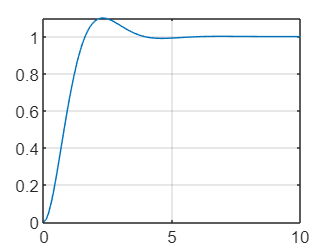

clc;clear;close all
for k = 0:0.01:10
    num = k;
    den = [1 2 k];
    m=10;
    sys=tf(num,den);
    omegan=sqrt(den(3));
    zeta=den(2)/(2*omegan);
    ts=4/(zeta*omegan);
    tp=pi/(omegan*sqrt(1-zeta^2));
    pos=exp(-zeta*pi/sqrt(1-zeta^2))*100;
    t=0:0.1:m;
    [yout,t]=step(sys,t);
    max_y = max(yout);
    
    if ( pos<=10 && pos>9.99 )
        k
        ts
        plot(t,yout)
        grid on
    end
    yss = polyval(num,0)/polyval(den,0);
    for i=1:m/0.1+1
        if yout(i)<0.9*yss
            t2=t(i);
        else if yout(i) == max_y
            break;
        end
    end
    end
end

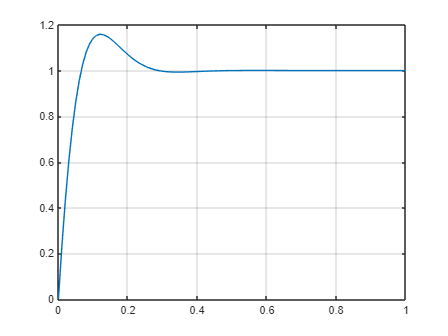

clc;clear all
omegan=20;
zeta=0.707;
a =25;
b =3.6;
kd = (2*zeta*omegan - b)/a;
kp = omegan^2/a;
num =[a*kd a*kp];
den = [1 2*zeta*omegan omegan^2];
sys=tf(num,den);
ts=4/(zeta*omegan);
tp=pi/(omegan*sqrt(1-zeta^2));
pos=exp(-zeta*pi/sqrt(1-zeta^2))*100;
t=0:0.01:1;
[yout,t]=step(sys,t);
max_y = max(yout);
plot(t,yout)
grid on